clc, clear all; close all;
s = tf('s');
Ts = 0.01;
z = tf('z',Ts);
Gs = 1/(s^2+3*s+1);
tss = 5;
Err = 0.1;
OS = 50;
[kp,ki,kd] = Code_magico(Gs,Ts,tss,Err,OS)

z1 = 0.9932 + 0.0288i

z2 = 0.9932 - 0.0288i

kp = 9.3231

ki =
 
  10
 
Static gain.
Model Properties


kd = -0.5333

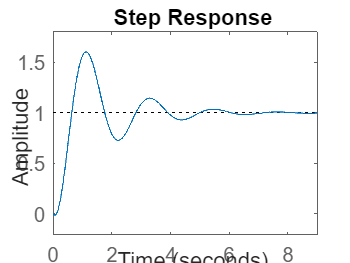


Gz = c2d(Gs,Ts,'zoh');
K=kp+ki*Ts*z/(z-1)+kd*(z-1)/z/Ts;
GCL=feedback(K*Gz,1);

step(GCL)

clc, clear all; close all;
s = tf('s');
Ts = 0.01;
z = tf('z',Ts);
Gs = 1/s/(s^2+s+1)

Gs =
 
        1
  -------------
  s^3 + s^2 + s
 
Continuous-time transfer function.
Model Properties


tss = 3;
Err = 0.1;
OS = 20;
[kp,ki,kd] = Code_magico(Gs,Ts,tss,Err,OS)

z1 = 0.9892 + 0.0206i

z2 = 0.9892 - 0.0206i

kp = -6.3131

ki =
 
  -2.232e-09
 
Static gain.
Model Properties


kd = 1.9813

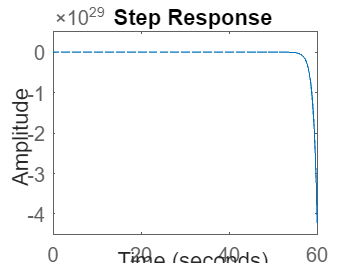


Gz = c2d(Gs,Ts,'zoh');
K=kp+ki*Ts*z/(z-1)+kd*(z-1)/z/Ts;
GCL=feedback(K*Gz,1);

step(GCL)

function [kp,ki,kd] = Code_magico(Gs,Ts,tss,Err,OS)

Gz = c2d(Gs,Ts,'zoh');
syms kp kd ki KD KP KI z;
Kz = kp+ki*Ts*z/(z-1)+kd*(z-1)/z/Ts;
ess = Ts/((z-1)*tfz_Sym(Gz)*Kz);
ees = limit(ess,z,1);
KI = solve(ees == Err, ki);
ki = Sym_tfs(solve(ees == Err, ki));

xi = log(100/OS)/sqrt(pi^2+log(100/OS)^2);
%tss = 3.2/(xi*wn)
wn = 3.2/(xi*tss);% 4 al 2%

s1=-xi*wn+i*wn*sqrt(1-xi^2);
s2=-xi*wn-i*wn*sqrt(1-xi^2);

z1 = exp(s1*Ts)
z2 = exp(s2*Ts)

K=KP+KI*Ts*z/(z-1)+KD*(z-1)/z/Ts;
Eq(1)=1+subs(K,z,z1)*evalfr(Gz,z1);
Eq(2)=1+subs(K,z,z2)*evalfr(Gz,z2);
A=solve(Eq);
kp=double(A.KP);
kd=double(A.KD);
end


function Zz = Sym_tfz(Gz,ts)
   [num_z, den_z] = numden(Gz); 
    num_coeff = sym2poly(num_z);
    den_coeff = sym2poly(den_z); 
    z = tf('z', ts); 
    Zz = zpk(tf(num_coeff, den_coeff, ts)); 
end

function Ss = Sym_tfs(Gs)
   [num_s, den_s] = numden(Gs); 
    num_coeff = sym2poly(num_s);
    den_coeff = sym2poly(den_s); 
    s = tf('s'); 
    Ss = tf(num_coeff, den_coeff); 
end

function Ss = tfs_Sym(Gs) 
    syms s
    [num, den] = tfdata(Gs, 'v'); 
    Ss = poly2sym(num, s) / poly2sym(den, s); 
end

function Zz = tfz_Sym(Gz) 
    syms z
    [num, den] = tfdata(Gz, 'v'); 
    Zz = poly2sym(num, z) / poly2sym(den, z); 
end
